load 'C:\class\coursefiles\mlbe\exercises\bostonTemps2005'
load 'C:\class\coursefiles\mlbe\exercises\tokyoTemps2005'
load 'C:\class\coursefiles\mlbe\exercises\bangaloreTemps2005'

bosTemp = boston_data(:,1);
tokTemp = tokyo_data(:,1);
banTemp = bangalore_data(:,1);

temps = [bosTemp,tokTemp,banTemp];
L = length(boston_data);    % all data is same size
days = 1:L

days =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



bosMean = mean(bosTemp);
tokMean = mean(tokTemp);
banMean = mean(banTemp);

bosMovAvg = movmean(bosTemp,50);
tokMovAvg = movmean(tokTemp,50);
banMovAvg = movmean(banTemp,50);

plot(temps)
hold on
plot([1 L],[bosMean bosMean],'r:')
plot([1 L],[tokMean tokMean],'g:')
plot([1 L],[banMean banMean],'b:')
title('Cities Maximum Daily Temperature - 2005')
xlabel('Day')
tempLabel = ['Temperature', 176, 'F']

tempLabel = Temperature°F

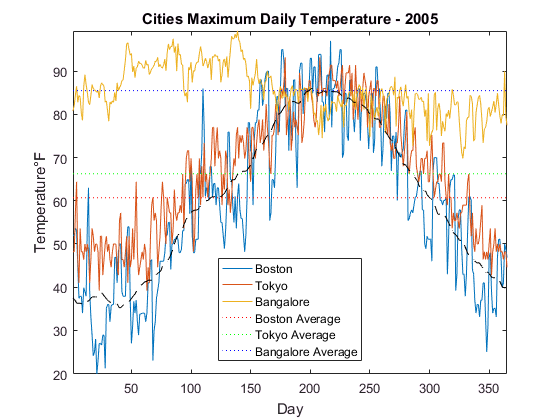

ylabel(tempLabel)
legend('Boston','Tokyo','Bangalore',...
        'Boston Average','Tokyo Average','Bangalore Average',...
        'Location','south')
axis tight
plot(days,bosMovAvg,'k--')
hold off


corrcoef(temps,'rows','complete')    % only rows without nans

ans =     1.0000    0.8645   -0.1296
    0.8645    1.0000   -0.1441
   -0.1296   -0.1441    1.0000


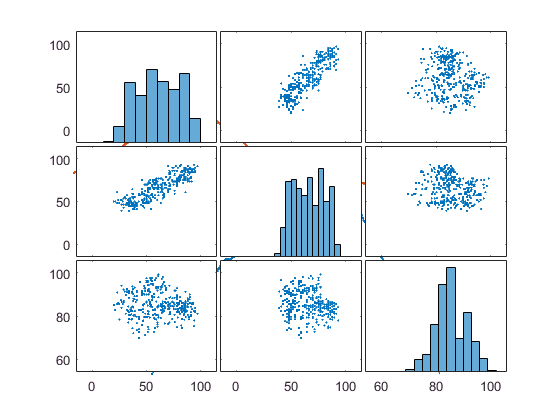

plotmatrix(temps)
hold off


hold on
plot(days,tokMovAvg,'.-')
plot(days,banMovAvg,'.-')
hold off